## Set up

clc
clear
clf
rng(16);

### Preprocessing

FullSet = readtable("Data\Process_data\measured_data_combined.csv");
X = FullSet(:,2:3);
X.f_LO_measured = FullSet.f_LO_measured;
X.f_LE_measured = FullSet.f_LE_measured;
X.c_RaffP_measured = FullSet.c_RaffP_measured;
X.c_RaffS_measured = FullSet.c_RaffS_measured;
X.c_BO_measured = FullSet.c_BO_measured;
% SmarketD.Direction = categorical(SmarketD.Direction);
% summary(SmarketD);
% Smarket = normalize(SmarketD(:,3:end-1));
% Smarket.Direction = SmarketD.Direction;
X_N = normalize(X);

y = FullSet.fault_state;

rng('default'); % For reproducibility
cv = cvpartition(y, 'Holdout', 0.3); % 70% training, 30% testing
X_train = X_N(training(cv), :);
y_train = y(training(cv));
X_test = X_N(test(cv), :);
y_test = y(test(cv));

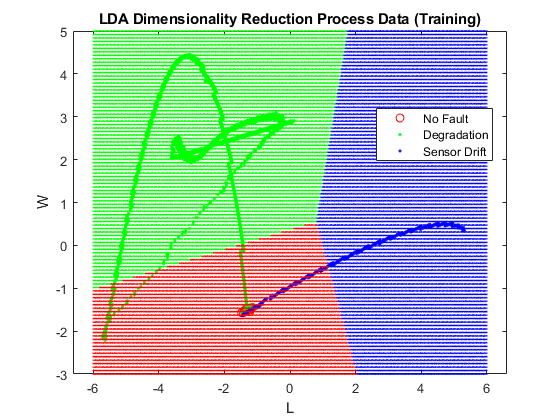


% Apply LDA for dimensionality reduction on the training data
num_components = 2; % Number of components in the reduced space
lda_model = fitcdiscr(X_train, y_train); % Fit the LDA model
[eigenvectors, eigenvalues] = eig(lda_model.BetweenSigma, lda_model.Sigma);
[~, sorted_indices] = sort(diag(eigenvalues), 'descend');
projection_matrix = eigenvectors(:, sorted_indices(1:num_components));

% Project training and testing data onto the LDA components
X_train_reduced = table2array(X_train) * projection_matrix;
X_test_reduced = table2array(X_test) * projection_matrix;

lda_reduced = fitcdiscr(X_train_reduced, y_train);
% isualization of training data in the reduced dimensional space
gscatter(X_train_reduced(:, 1), X_train_reduced(:, 2), y_train, 'rgb', 'o..');
title('LDA Dimensionality Reduction Process Data (Training)');
xlabel('LDA Component 1');
ylabel('LDA Component 2');

[L, W] = meshgrid(linspace(-6, 6, 500), linspace(-3,5,100)); ...
L = L(:);
W = W(:);
pred = lda_reduced.predict([L W]);
hold on;
h = gscatter(L, W, pred, 'rgb', '.', 0.1, 'off'); set(h, 'LineWidth', 0.01, 'MarkerSize', 0.01)
legend('No Fault', 'Degradation', 'Sensor Drift', '', '', '');
hold off; 


% Predict on the test data and calculate the confusion matrix
y_pred = predict(lda_reduced, X_test_reduced);
C = confusionmat(y_test, y_pred);
disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

        9304           0           0
        2367        6273           0
         608           0        7368



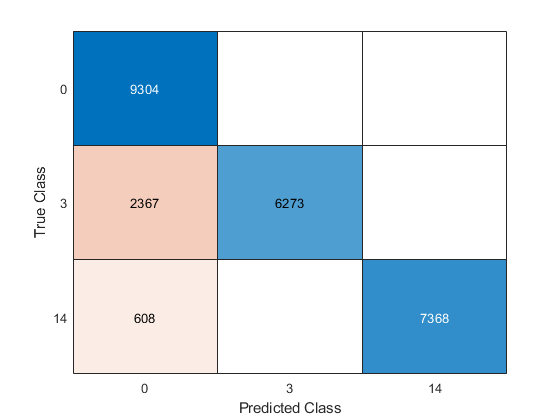


confusionchart(y_test, y_pred)

mean(y_pred == y_test)

ans = 0.8852

50% threshold

sum(ldaPredPosterior(:,1) >= 0.5)

ans = 12275

sum(ldaPredPosterior(:,1) < 0.5)

ans = 13645

ldaPredPosterior(1:20,1).'

ans =     0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9912    0.9922    0.9923    0.9923    0.9923    0.9924    0.9925    0.9918    0.9917    0.9917    0.9916


ldaPredClass(1:20,1).'

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% 90 %
sum(ldaPredPosterior(:,1) >= 0.9)

ans = 11159